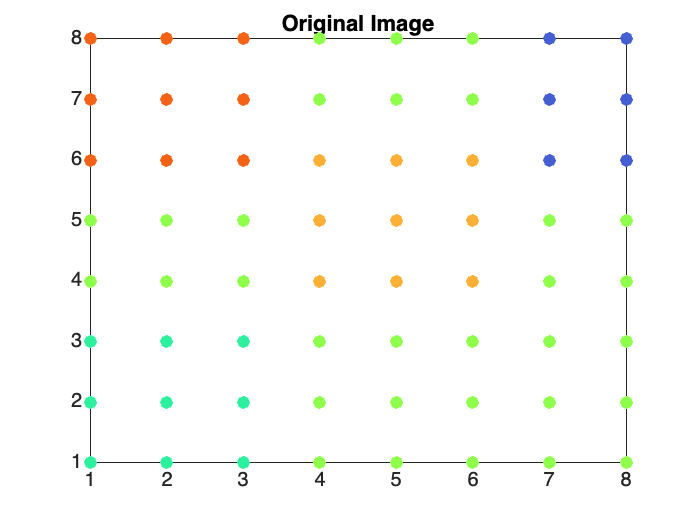

% Define a 4X4 image // small numbers are dark, large numbers are white
A = 10*ones(8,8);
A(1:3,1:3) = 8;
A(4:6, 4:6) = 14;
A(1:3, 6:8) = 16;
A(7:8, 6:8) = 3;
c = turbo(20); 
figure
[n,m] = size(A);
NM = n*m;
figure
for i = 1:n
    for j = 1:m
        plot(i,j, 'o', 'Color', c(A(i,j),:), MarkerFaceColor=c(A(i,j),:))
        hold on
    end
end
title('Original Image')
hold off

% Define labels
L = [1, 2, 3]; % 1 - red, 2 - greeb, 3 - blue
% Define seeds
S = [1, 8, 1; 5, 6, 1; 3, 3, 2; 6, 3, 2; 5, 8, 2; 8,7, 3; 7, 8, 3];
T = 1000; % Number of steps
LD = zeros(NM, numel(L));  % initalize limiting distribution
img = zeros(n,m,3);
for p = 1:3
    for i = 1:n
        for j = 1:m
            img(i,j,p) = c(A(i,j),p);
        end
    end
end

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 0.002413 seconds.


tic
H = construct_hamiltonian(W, 0.1);
toc

Elapsed time is 0.001707 seconds.


% U = construct_operator(H);

for i = 1:numel(L)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        A_sub(subset(p,2) + m*(subset(p,1)-1)) = 1; %A(subset(p,1), subset(p,2));
    end
    state = 1/subset_length * A_sub;
    D = zeros(NM,T);
    for t = 1:T
        state = update_state(-1i,H,state);
        D(:,t) = retrieve_position(state);
    end
    LD(:,i) = 1/T * sum(D,2);
end

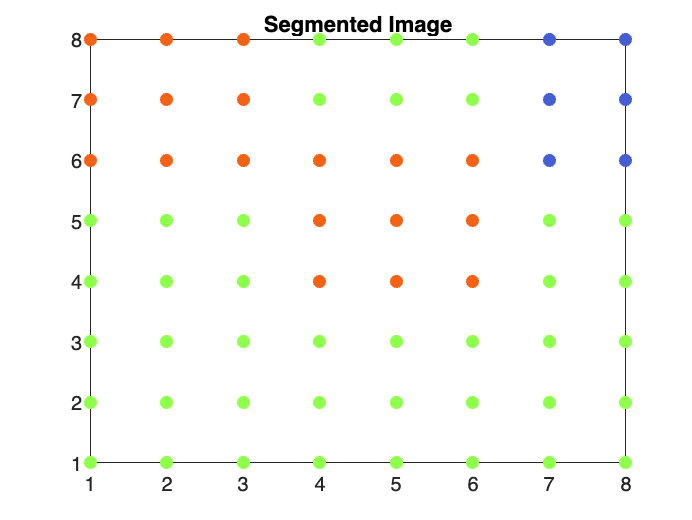

B = zeros(n,m);
b = [16, 10, 3];
figure
for i = 1:m
    for j = 1:n
        k = find_seed(LD,i,j,m);
        B(i,j) = k;
        plot(i,j, 'o', "Color", c(b(B(i,j)),:), MarkerFaceColor=c(b(B(i,j)),:))
        hold on
    end
end
title('Segmented Image')
hold off